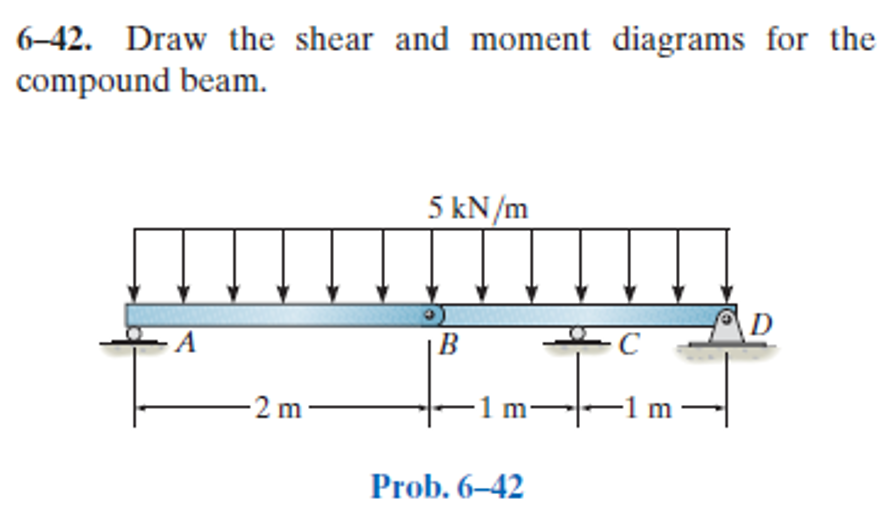

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-42P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-42P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('hinge', 'force', 'Hb', 2*u.m);
b = b.add('reaction', 'force', 'Rc', 3*u.m);
b = b.add('reaction', 'force', 'Rd', 4*u.m);
b = b.add('distributed', 'force', -5*u.kN/u.m, [0 4]*u.m);
b.L = 4*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(x^{3}-4\,x^{2}\,m+19\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 2\,m\\ \frac{5\,\left(x-3\,m\right)\,\left(-x^{3}+x^{2}\,m+3\,x\,m^{2}+20\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(2\,m,3\,m\right]\\ -\frac{5\,\left(x-3\,m\right)\,\left(x-4\,m\right)\,\left(x^{2}-13\,x\,m+41\,m^{2}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(4\,x^{3}-12\,x^{2}\,m+19\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 2\,m\\ \frac{5\,\left(-4\,x^{3}+12\,x^{2}\,m+11\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(2\,m,3\,m\right]\\ -\frac{5\,\left(4\,x^{3}-60\,x^{2}\,m+288\,x\,m^{2}-443\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(x-2\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -\frac{5\,\left(x-4\,m\right)\,\left(x-6\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -5\,\left(x-1\,m\right)\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -5\,\left(x-5\,m\right)\,\frac{\mathrm{kN}}{m} & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = -5\,\frac{\mathrm{kN}}{m}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 5\,\mathrm{kN}\\ \mathrm{Rc} & 20\,\mathrm{kN}\\ \mathrm{Rd} & -5\,\mathrm{kN} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & 5\,\mathrm{kN} \end{array}\right)$$

# shear and moment diagram

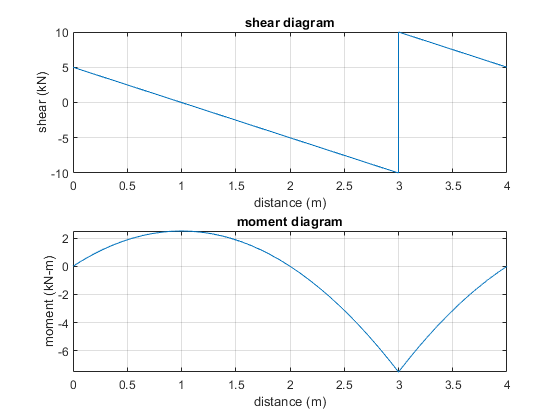

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;